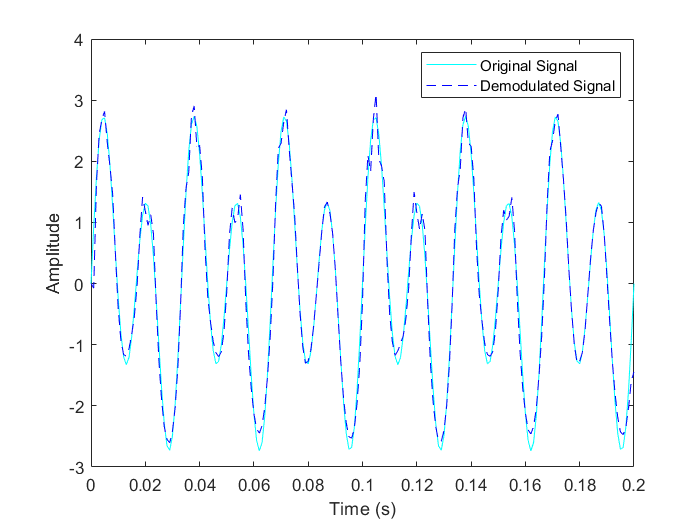

%setting the sampling frequency to 1kHz and carrier frequency to 200 Hz. Generate a time vector having a duration of 0.2 s.
fs = 1000; 
fc = 200;  
t = (0:1/fs:0.2)';

%Creating two-tone sinusoidal signal with frequencies 30 and 60 Hz.
x = sin(2*pi*30*t)+2*sin(2*pi*60*t);

fDev = 50; %Setting the frequency deviation to 50 Hz.

y = fmmod(x,fc,fs,fDev);%Frequency modulate x.

z = fmdemod(y,fc,fs,fDev);%Demodulate z.

%Plot the original and demodulated signals.
plot(t,x,'c',t,z,'b--');
xlabel('Time (s)')
ylabel('Amplitude')
legend('Original Signal','Demodulated Signal')